# For combinations sizes (nodes) and densities (edges) of the TTr embedded network, 100 random networks for each case are created

## Reading the 100 random network 'data' for every 'TOPOnnee'

clear all

% In the 'TTr' folder directories named as 'TOPOnnee' are present where
% nn is the number of nodes in the random network (including TTr nodes)
% ee is the number of edges in the random network (excluding TTr edges)

% path to the TTr folder
% folder_path_parent = 'TTr';

folder_path_parent = ['/Users/atchutasrinivasduddu/Library/CloudStorage/' ...
    'OneDrive-IndianInstituteofScience/Duddu/2023/Fall 2023/' ...
    'Toggle Tetrahedron/Embedded boolean/TTr'];

cd(folder_path_parent);
% shortlist all 'TOPOnnee' folders
list_topos = dir('TOPO*');

% loop over all the 'TOPOnnee' folders
for i = 1:numel(list_topos)

% path to the child folder
folder_path_child = strcat(getfield(list_topos,{i},'name'));
cd(folder_path_child);
% all the csv files present in the ith 'TOPOnnee' folder
list_csv_files = dir('*.csv');

% reading the data from each csv into tables
file_names = string(char(list_csv_files.name));
for j=1:length(file_names)
    % data is struct containing all csv data for a particular 'TOPOnnee'
   final_data.data(i).(strcat('RN',num2str(j))) = readtable(file_names(j));
end
% % final_data is struct containing data for every 'TOPOnnee' folder
% final_data.(getfield(list_topos,{i},'name')) = data;

cd ..
end

## Shortlisting the cases corresponding to the 4 SP and 6 DP states and calculating their sum frequrncies in each of the TOPOnnee and for every Random Network (RN)

% F2 or the 6 DP states of TTr
TTr_dp = ['0011';'0101';'0110';'1001';'1010';'1100'];
% F1 or the 4 SP states of TTr
TTr_sp = ['1000';'0100';'0010';'0001'];
% Number of random networks and fieldnames to access them later
RN_number = fieldnames(final_data.data);
% matrix to save frequency data of each of the 6 DP states for 
% every TOPOnnee and for all the 100 random networks
all_frequency_dp_states = zeros(length(TTr_dp),numel(list_topos) ...
    ,length(RN_number));
% matrix to save frequency data of each of the 4 SP states for 
% every TOPOnnee and for all the 100 random networks
all_frequency_sp_states = zeros(length(TTr_sp),numel(list_topos) ...
    ,length(RN_number));


% loop level 1 over all the TOPOnnee folders
for j = 1:numel(list_topos)

% loop level 2 over all the 100 random networks
for i = 1:length(RN_number)

    % for the F2 or the 6 DP states
    temp_frequency_dp = zeros(length(TTr_dp),1);
    temp_data = final_data.data(j).(RN_number{i});
    % choose the ABCD expressions from all the nodes of the RN
    temp_ABCD_values = char(table2array(temp_data(:,1)));
    temp_ABCD_values(:,[1,end]) = [];
    temp_ABCD_values = string(temp_ABCD_values(:,1:4));
    % select only the 6 DP states by comparing the expressions
    only_dp = ismember(temp_ABCD_values,TTr_dp);
    temp_ABCD_values = temp_ABCD_values(only_dp);
    temp_data = temp_data(only_dp,:);
    [C,ia,ic] = unique(temp_ABCD_values);
    state_check = ismember(TTr_dp,C);
    % counting the frequencies of each of the 6 DP states
    temp_frequency_dp(logical(state_check)) = accumarray(ic, ...
        table2array(temp_data(:,3)));
    all_frequency_dp_states(:,j,i) = temp_frequency_dp;


    % for the F1 or the 4 SP states
    temp_frequency_sp = zeros(length(TTr_sp),1);
    temp_data = final_data.data(j).(RN_number{i});
    % choose the ABCD expressions from all the nodes of the RN
    temp_ABCD_values = char(table2array(temp_data(:,1)));
    temp_ABCD_values(:,[1,end]) = [];
    temp_ABCD_values = string(temp_ABCD_values(:,1:4));
    % select only the 4 SP states by comparing the expressions
    only_sp = ismember(temp_ABCD_values,TTr_sp);
    temp_ABCD_values = temp_ABCD_values(only_sp);
    temp_data = temp_data(only_sp,:);
    [C,ia,ic] = unique(temp_ABCD_values);
    state_check = ismember(TTr_sp,C);
    % counting the frequencies of each of the 4 SP states
    temp_frequency_sp(logical(state_check)) = accumarray(ic, ...
        table2array(temp_data(:,3)));
    all_frequency_sp_states(:,j,i) = temp_frequency_sp;
end
% end of loop level 2

end
% end of loop level 1


% finding sum of frequencies of the 4 SP and 6 DP states respectively
% for each TOPOnnee and every RN
freq_sum_SP(:,:) = sum(all_frequency_sp_states);
freq_sum_DP(:,:) = sum(all_frequency_dp_states);

## Making boxcharts showing the sum frequencies of the 4 SP (Single-Positive or F1) and the 6 DP (Double-Positive or F2) states

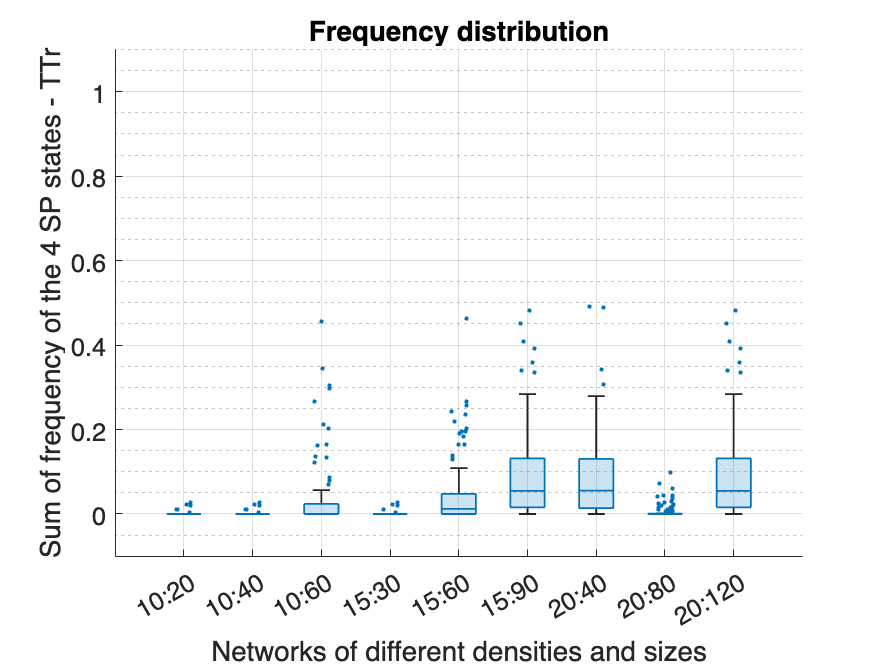

% boxchart corresponding to the F1 or SP states
figure()
b = boxchart(freq_sum_SP');
b.JitterOutliers = 'on';
b.MarkerStyle = '.';
b.MarkerSize = 7;
ylim([-0.1 1.1]);
xlabel('Networks of different densities and sizes','FontSize',14);
xticklabels({'10:20','10:40','10:60','15:30','15:60','15:90' ...
    ,'20:40','20:80','20:120'});
ylabel('Sum of frequency of the 4 SP states - TTr','FontSize',14);
title('Frequency distribution','FontSize',18);
grid(gca,'minor');
grid on
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',14)

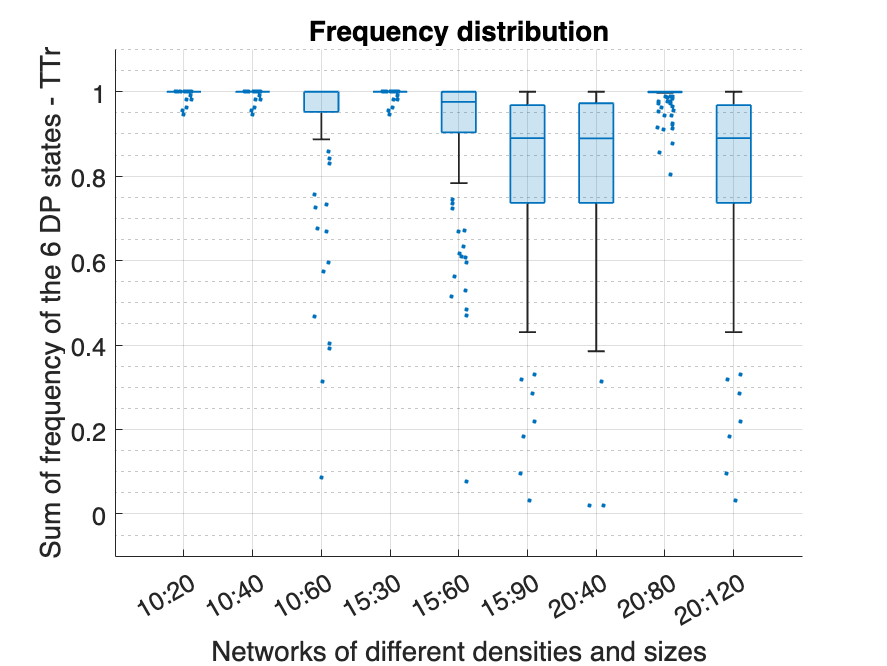


% boxchart corresponding to the F2 or DP states
figure()
b = boxchart(freq_sum_DP');
b.JitterOutliers = 'on';
b.MarkerStyle = '.';
b.MarkerSize = 7;
ylim([-0.1 1.1]);
xlabel('Networks of different densities and sizes','FontSize',14);
xticklabels({'10:20','10:40','10:60','15:30','15:60','15:90' ...
    ,'20:40','20:80','20:120'});
ylabel('Sum of frequency of the 6 DP states - TTr','FontSize',14);
title('Frequency distribution','FontSize',18);
grid(gca,'minor');
grid on
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',14)

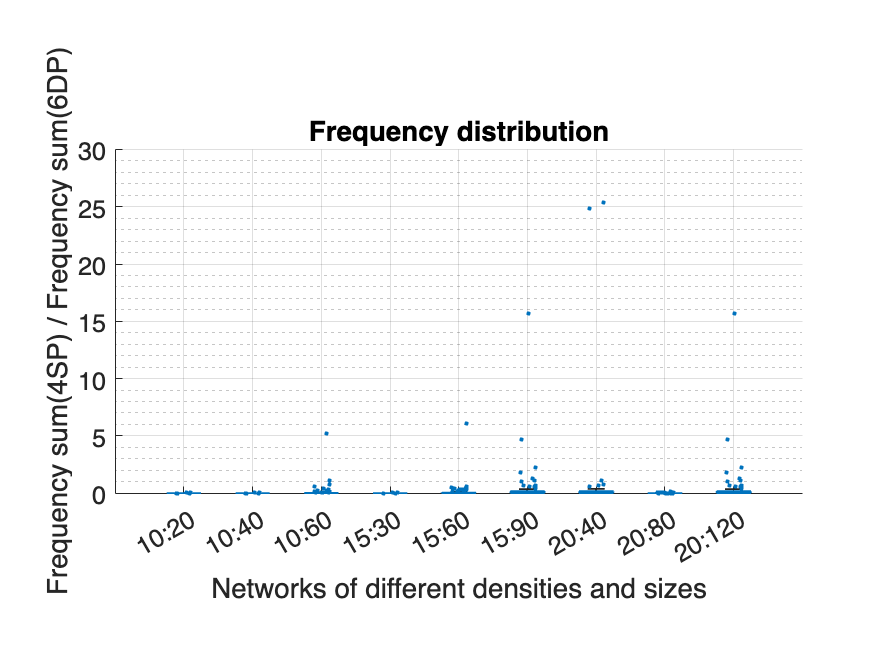


% boxchart corresponding to the fraction - F1/F2
fraction_F1_over_F2 = freq_sum_SP./freq_sum_DP;
figure()
b = boxchart(fraction_F1_over_F2');
b.JitterOutliers = 'on';
b.MarkerStyle = '.';
b.MarkerSize = 7;
% ylim([-0.1 3]); % yaxis limits
xlabel('Networks of different densities and sizes','FontSize',16);
xticklabels({'10:20','10:40','10:60','15:30','15:60','15:90' ...
    ,'20:40','20:80','20:120'});
ylabel('Frequency sum(4SP) / Frequency sum(6DP)','FontSize',16);
title('Frequency distribution','FontSize',20);
grid(gca,'minor');
grid on
% set(gca,'YScale','log')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',14)
pbaspect([6 3 1]);

## Making scatter plot showing F2 vs F1 and the x=y line

% % for TT F2/F1
% figure()
% mycolours = [0.0742    0.3086    0.3750; 0.3125    0.4961    0.5508;0.6289    0.7852    0.8672;0.0742    0.3086    0.3750; 0.3125    0.4961    0.5508;0.6289    0.7852    0.8672;0.0742    0.3086    0.3750; 0.3125    0.4961    0.5508;0.6289    0.7852    0.8672];
% b = scatter(freq_sum_SP',freq_sum_DP',[],mycolours);
% ylim([-0.1 1.1]);
% xlim([-0.1 1.1]);
% % xlabel('Networks of different densities and sizes','FontSize',14);
% % xticklabels({'10:20','10:40','10:60','15:30','15:60','15:90' ...
% %     ,'20:40','20:80','20:120'});
% % ylabel('Sum of frequency of the 3 DP states - TT','FontSize',14);
% % title('Frequency distribution','FontSize',18);
% % grid(gca,'minor');
% % grid on

## Making histograms showing the distribution of the fraction F1/F2 for each of the 9 TOPOnnee and all of them together as well

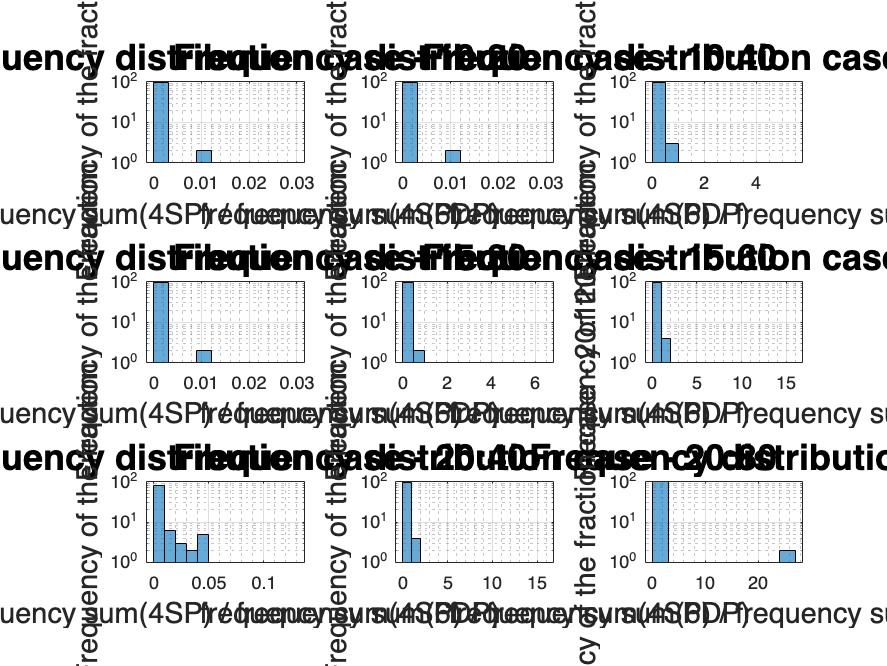

% 9 subplots corresponding to each of the TOPOnnee
figure()
subplot(3,3,1)
h = histogram(fraction_F1_over_F2(1,:));
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution case - 10:20','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
subplot(3,3,2)
h = histogram(fraction_F1_over_F2(2,:));
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution case - 10:40','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
subplot(3,3,3)
h = histogram(fraction_F1_over_F2(3,:));
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution case - 10:60','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
subplot(3,3,4)
h = histogram(fraction_F1_over_F2(4,:));
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution case - 15:30','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
subplot(3,3,5)
h = histogram(fraction_F1_over_F2(5,:));
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution case - 15:60','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
subplot(3,3,6)
h = histogram(fraction_F1_over_F2(6,:));
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution case - 15:90','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
subplot(3,3,7)
h = histogram(fraction_F1_over_F2(8,:));
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution case - 20:40','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
subplot(3,3,8)
h = histogram(fraction_F1_over_F2(9,:));
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution case - 20:80','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
subplot(3,3,9)
h = histogram(fraction_F1_over_F2(7,:));
xlabel('Networks of different densities and sizes','FontSize',16);
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction case - 20:120','FontSize',16);
title('Frequency distribution','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')

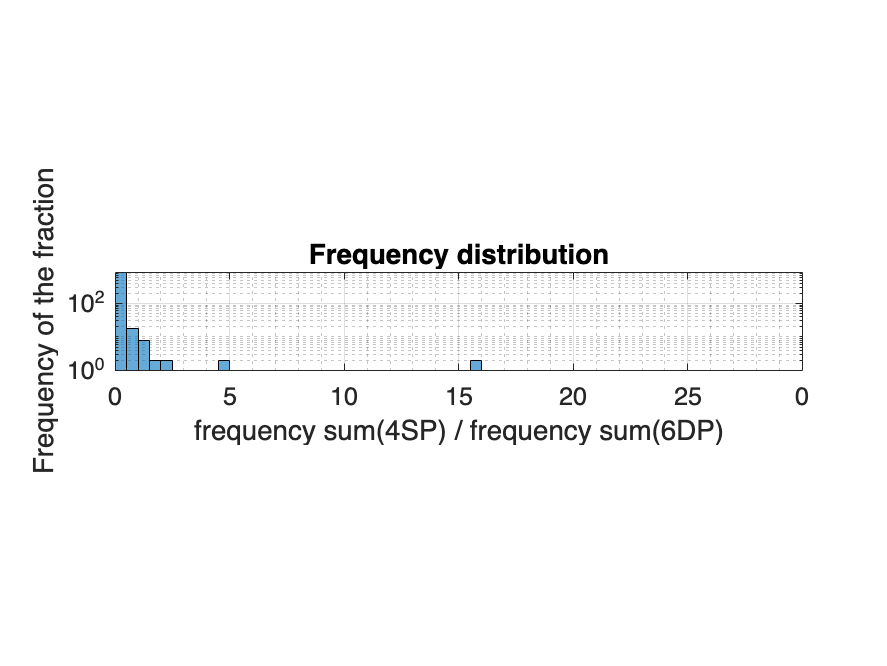


% histogram taking all the nine cases together
figure()
h = histogram(fraction_F1_over_F2);
xlabel('frequency sum(4SP) / frequency sum(6DP)','FontSize',16);
ylabel('Frequency of the fraction','FontSize',16);
title('Frequency distribution','FontSize',20);
grid(gca,'minor');
grid on
set(gca,'YScale','log')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',14)
pbaspect([14 2 1]);